load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\'Prueba_Motor_0,2V' % para cargar el experimento a 0.2 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\'Prueba_Motor_0,2V_negativo' % para cargar el experimento a 0.2 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_1V % para cargar el experimento a 1 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_1V_negativo% para cargar el experimento a -1 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_2V % para cargar el experimento a 2 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_2V_negativo % para cargar el experimento a -2 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_4V % para cargar el experimento a 4 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_4V_Negativo% para cargar el experimento a -4 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_5V % para cargar el experimento a 5 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_5V_negativo% para cargar el experimento a -5 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_6V % para cargar el experimento a 6 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_6V_negativo% para cargar el experimento a -6 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_8V % para cargar el experimento a 8 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_8V_negativo% para cargar el experimento a -8 V


Pruebas con el archivo de 0.2V(Señal minima para el funcionamiento del motor)

tiempo = Prueba_Motor_0_2V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_0_2V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_0_2V(:,3); % vector columna de valores de la salida
ts_acumulado=0;

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final =mean(salida(x_fin-10):salida(x_fin - 1)) 
ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini
cnt=1
ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y


_______________________________________________________________________________________________________________________

Pruebas con el archivo de -0.2V(Señal minima para el funcionamiento del motor pero de manera inversa)

tiempo = Prueba_Motor_0_2V_negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_0_2V_negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_0_2V_negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y
%Seleccion de la parte de interes de la grafica

Establecimiento de intervalos de interes:

t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final =mean(salida(x_fin-10):salida(x_fin - 1)) 
ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini
cnt=cnt+1
ts_acumulado= (ts_acumulado+ts)

Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de 1V

tiempo = Prueba_Motor_1V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_1V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_1V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y


Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final =mean(salida(x_fin-10):salida(x_fin - 1)) 
ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini
cnt=cnt+1

ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y


________________________________________________________________________________________________________________________

Pruebas con el archivo de -2V

tiempo = Prueba_Motor_1V_negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_1V_negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_1V_negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y


Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final =mean(salida(x_fin-10):salida(x_fin - 1)) 
ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini
cnt=cnt+1

ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y



________________________________________________________________________________________________________________________

Pruebas con el archivo de 2V

tiempo = Prueba_Motor_2V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_2V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_2V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y


Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10):salida(x_fin - 1)) 
ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini
cnt=cnt+1

ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y


________________________________________________________________________________________________________________________

Pruebas con el archivo de -2V

tiempo = Prueba_Motor_2V_negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_2V_negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_2V_negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y


Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final =mean(salida(x_fin-10):salida(x_fin - 1)) 
ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini
cnt=cnt+1

ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de 4V

tiempo = Prueba_Motor_4V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_4V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_4V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y


Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1))  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada))
x_ini = find(tiempo==t_ini) % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin) % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

%valor_final = mean(salida(x_fin - 10):salida(x_fin - 1)) 
%ts = tiempo(find(salida >= (0.95*valor_final),1))-t_ini
%cnt=cnt+1
%ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y


________________________________________________________________________________________________________________________

Pruebas con el archivo de -4V

tiempo = Prueba_Motor_4V_Negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_4V_Negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_4V_Negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y


Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

%valor_final =mean(salida(x_fin-10):salida(x_fin - 1)) 
%ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini
%cnt=cnt+1
%ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de 5V

tiempo = Prueba_Motor_5V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_5V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_5V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y


Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final =mean(salida(x_fin-10):salida(x_fin - 1)) 
ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini
cnt=cnt+1

ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y


________________________________________________________________________________________________________________________

Pruebas con el archivo de -5V

tiempo = Prueba_Motor_5V_negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_5V_negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_5V_negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y


Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final =mean(salida(x_fin-10):salida(x_fin - 1)) 
ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini
cnt=cnt+1

ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y


________________________________________________________________________________________________________________________

Pruebas con el archivo de 6V

tiempo = Prueba_Motor_6V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_6V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_6V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y


Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final =mean(salida(x_fin-10):salida(x_fin - 1)) 
ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini
cnt=cnt+1
ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y


________________________________________________________________________________________________________________________

Pruebas con el archivo de -6V

tiempo = Prueba_Motor_6V_negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_6V_negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_6V_negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y


Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final =mean(salida(x_fin-10):salida(x_fin - 1)) 
ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini
cnt=cnt+1

ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de 8V

tiempo = Prueba_Motor_8V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_8V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_8V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y


Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final =mean(salida(x_fin-10):salida(x_fin - 1)) 
ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini
cnt=cnt+1

ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y


________________________________________________________________________________________________________________________

Pruebas con el archivo de -8V

tiempo = Prueba_Motor_8V_negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_8V_negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_8V_negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y


Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

%valor_final =mean(salida(x_fin-10):salida(x_fin - 1)) 
%ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini
ts_acumulado= (ts_acumulado+ts)


Figura con los datos de interes:

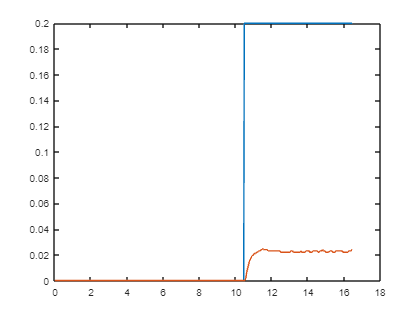

valor_final = 0.0220

ts = 0.5280

cnt = 1

ts_acumulado = 0.5280

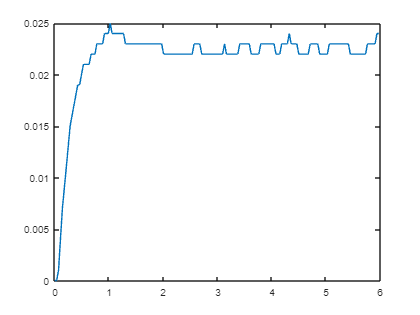

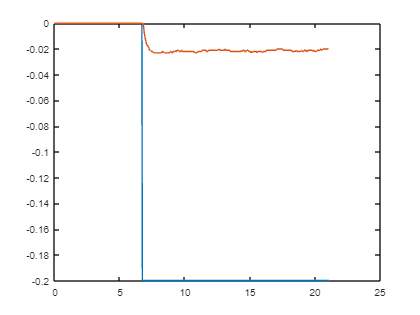

valor_final = -0.0200

ts = 0.4920

cnt = 2

ts_acumulado = 1.0200

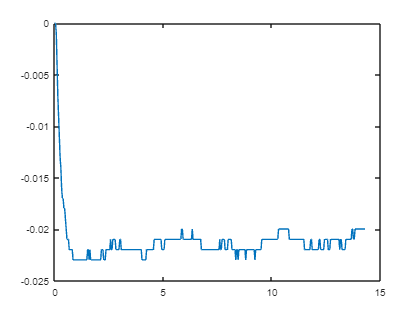

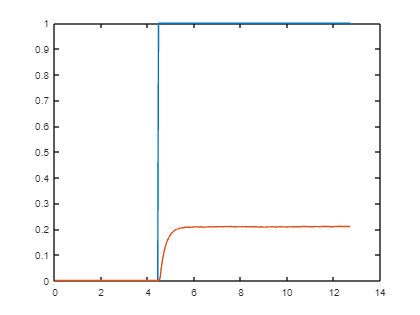

valor_final = 0.2100

ts = 0.8100

cnt = 3

ts_acumulado = 1.8300

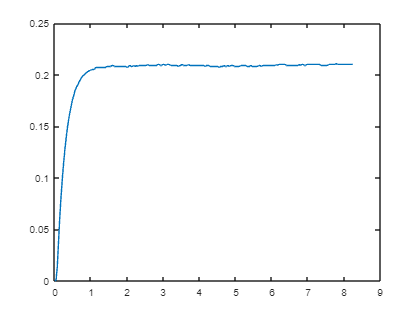

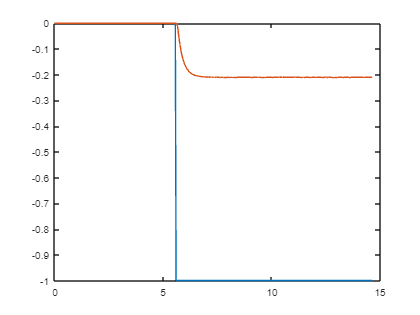

valor_final = -0.2110

ts = 0.8420

cnt = 4

ts_acumulado = 2.6720

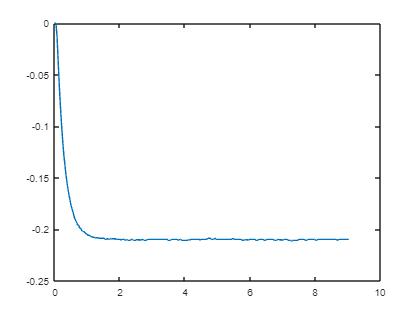

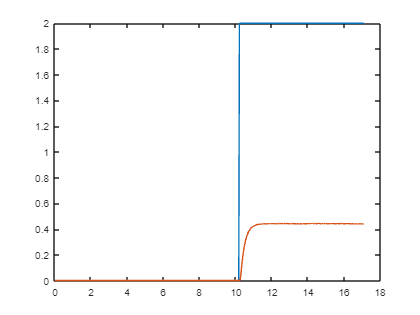

valor_final = 0.4390

ts = 0.7400

cnt = 5

ts_acumulado = 3.4120

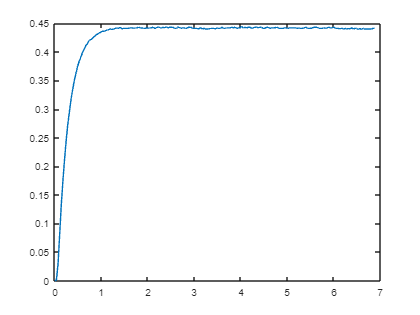

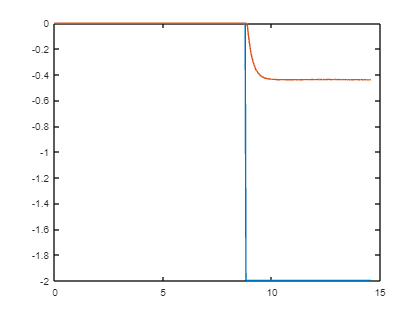

valor_final = -0.4400

ts = 0.8090

cnt = 6

ts_acumulado = 4.2210

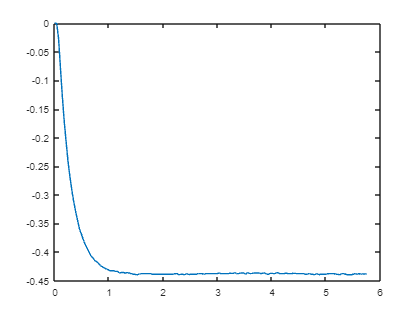

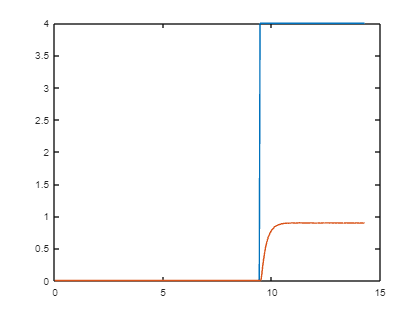

t_ini = 9.4600

t_fin = 14.2750

x_ini = 269

x_fin = 406

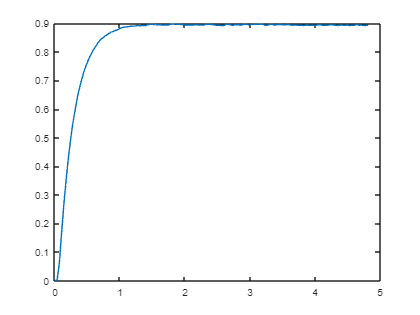

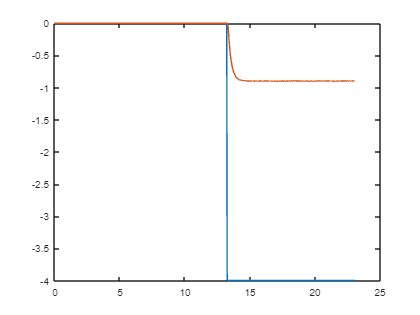

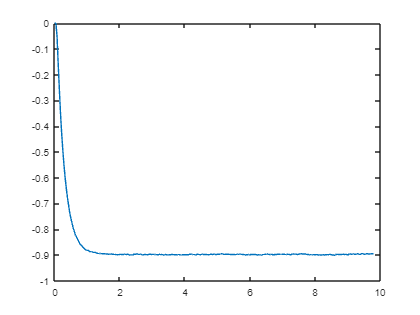

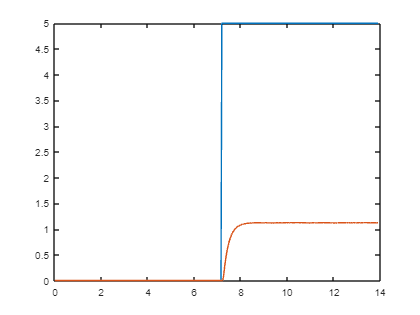

valor_final = 1.1220

ts = 0.7720

cnt = 7

ts_acumulado = 4.9930

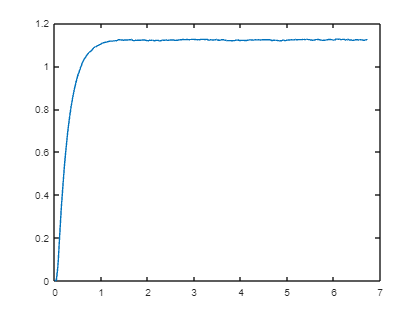

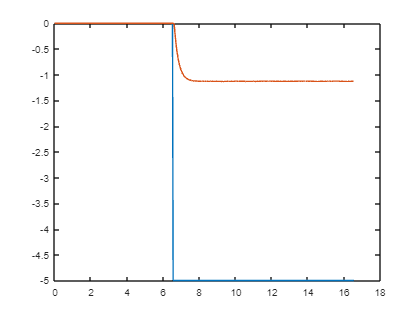

valor_final = -1.1280

ts = 0.7750

cnt = 8

ts_acumulado = 5.7680

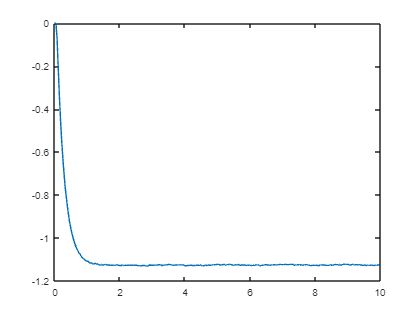

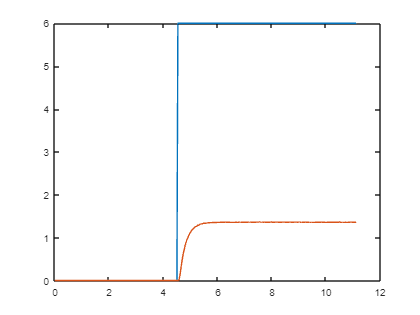

valor_final = 1.3560

ts = 0.7730

cnt = 9

ts_acumulado = 6.5410

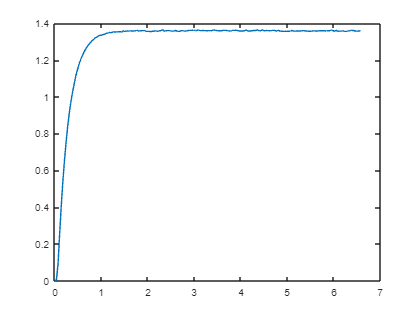

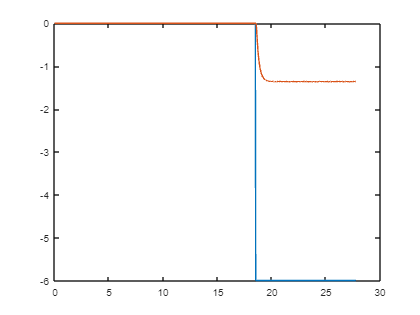

valor_final = -1.3620

ts = 0.7740

cnt = 10

ts_acumulado = 7.3150

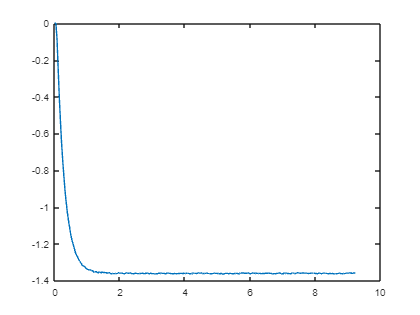

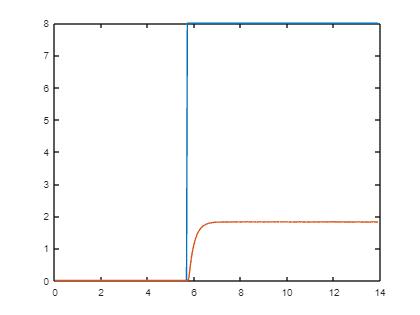

valor_final = 1.8210

ts = 0.7750

cnt = 11

ts_acumulado = 8.0900

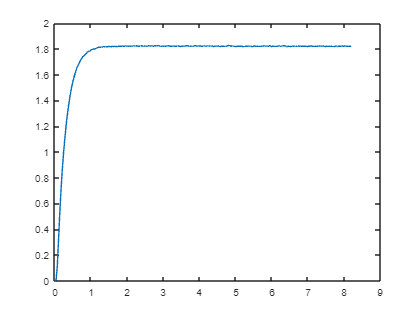

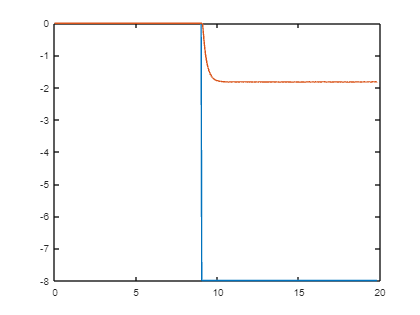

ts_acumulado = 8.8650

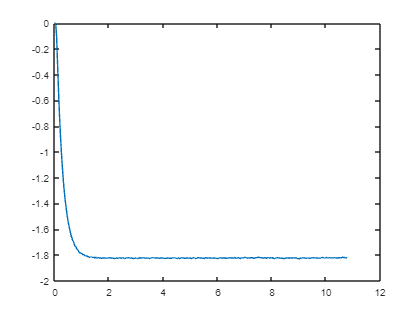

media_ts = 0.8059

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

media_ts=ts_acumulado/cnt
